# FFT - Iterative Implementation of the Fast Fourier Transform

## Fast Re-ordering of Samples

In the recursive FFT implementation signal samples are even/odd partitioned many times. In contrary, in an iterative  implementation of the FFT algorithm each signal sample comes directly from its input position to the final position which is the same as after multi-level partition of samples. This new sample position is found as follows:

- the sample index is written as an unsigned integer number in binary system,

- position of all bits is left/right reversed (flipped) (now they are written from LSB to MSB).

 and **position of all bits is left/right reversed** (now they are written from LSB to MSB).

See figure below explaining this procedure for $N=8$. For example (**old** sample number $\rightarrow$** new** sample number):

**3 = 011b  **$\rightarrow$**  110b = 6**

**4 = 100b  **$\rightarrow$**  001b = 1**.

 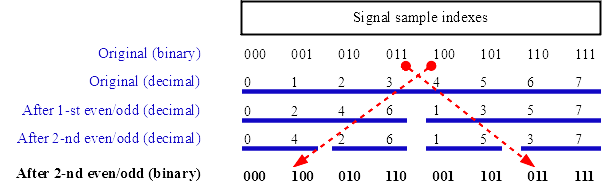

## 2-Point DFTs

After samples re-ordering,  $N/2$  2-point DFTs are performed upon pairs of samples, in the figure above upon the following pairs:

$[ x(0), x(4) ],  \;\;\;\; [ x(2), x(6) ],  \;\;\;\;  [ x(1), x(5) ],  \;\;\;\;  [ x(3), x(7) ]$.

The 2-sample DFT is defined as ($y(n)$ - input, $Y(k)$ - output):

$\left\lbrack \begin{array}{c}
Y\left(0\right)\\
Y\left(1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & e^{-j\pi } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\left(0\right)\\
y\left(1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\left(0\right)\\
y\left(1\right)
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left\lbrace \begin{array}{ll}
Y\left(0\right)=y\left(0\right)+y\left(1\right) & \\
Y\left(1\right)=y\left(0\right)-y\left(1\right) & 
\end{array}\right.\;\;\;$.

and it consists only of one addition and one subtraction.

## Iterative DFT spectra combining

Then 2-point spectra are combined into 4-point ones, 4-point into 8-point, and so on, according to the general spectrum accumulation equation:

$X^{(K)}(k) = [ X_e^{(K/2)}(k_1), \;\; X_e^{(K/2)}(k_1)] + e^{-j \frac{2\pi}{K} k}  \cdot [ X_o^{(K/2)}(k_1)  \;\; X_o^{(K/2)}(k_1) ]$,

where:

- $K=4,8,16,...,N$- length of the one combined $K$-samples long spectrum $X^{(K)}(k)$,

- $k=0,1,...,K-1$ - indexes of the combined spectrum,

- $k_1=0,1,...,K/2-1$ - indexes of even/odd $K/2$-samples long spectra $X_{e/o}^{(K/2)}(k_1)$ being combined, two times shorter than $X^{(K)}(k)$. 

## Testing

**Analyze the Matlab code** of the iterative Radix-2 DIT FFT function presented below. Run the program. Change signal length and values of its samples.

clear all;                       % clear all variables
N = 8; x = rand(1,N);            % analyzed signal, N=2^p
Xm = fft(x);                     % its DFT (FFT) computed by Matlab 
X = myIterFFT(x);                % calling iterative FFT procedure
error = max( abs( X - Xm ) ),    % error

error = 2.7336e-16

function y = myIterFFT(x)
% My non-recursive radix-2 FFT function
N = length(x);          % number of signal samples
Nbits = log2(N);        % number of bits for sample indexes, e.g. N=8 -> Nbit=3

% Samples reordering (in bitreverse fashion)
% x = 0:N-1;            % only for test
  n = 0:N-1;            % indexes of ALL samples 
  m = dec2bin(n);       % bits of these indexes
  m = m(:,Nbits:-1:1);  % reversal of these bits
  m = bin2dec(m);       % new indexes of ALL samples
  y(m+1) = x(n+1);      % data reordering
% y, pause              % checking the re-ordering result

% ALL 2-point DFTs upon the neighboring pairs of partitioned (sorted) data
  y = [ 1  1; ...
        1 -1] * [ y(1:2:N); ...
                  y(2:2:N) ];
  y = y(:)';

% N-point DFT spectrum reconstruction  
% DFT spectra: 2-point --> 4-point --> 8-point --> 16-point ...
  Nx = N;                   % number of samples (changing variable length)
  Nlevels = Nbits;          % number of levels of computations equal to log2(Nx)
  N = 2;                    % initial DFT length after 2-point DFTs
  for lev = 2 : Nlevels                % next LEVEL
      N = 2*N;                         % new DFT spectrum length after combining 
      Nblocks = Nx/N;                  % number of new DFT spectra after combining 
      W = exp( -j*2*pi/N*(0:N-1) );    % correction term on this level
      for k = 1 : Nblocks                                 % next BLOCK of 2 even/odd DFTs
          y1 = y( 1     + (k-1)*N : N/2 + (k-1)*N );      % y1 even (LOWER) spectrum 
          y2 = y( N/2+1 + (k-1)*N : N   + (k-1)*N );      % y2 odd  (UPPER) spectrum
          y(1 + (k-1)*N : N + (k-1)*N ) = [ y1 y1 ] + W .* [ y2 y2 ];  % combining y1,y1 & y2,y2
      end
  end
end